## Space-Time Curve of Random Walkers

rng(0); %setting the seed
z = rand(1000,10000); %creating a random array of 1000x10000
z(z > 0.5)=1;
z(z <= 0.5)=-1;
q= cumsum(z)./1000;

Using $\texttt{cumsum(.)}$ we find the distplacement of walker at time $t$

t = 1000;
time = 1:t;

Plotting positions of $1^{st}$ 1000 walkers against time

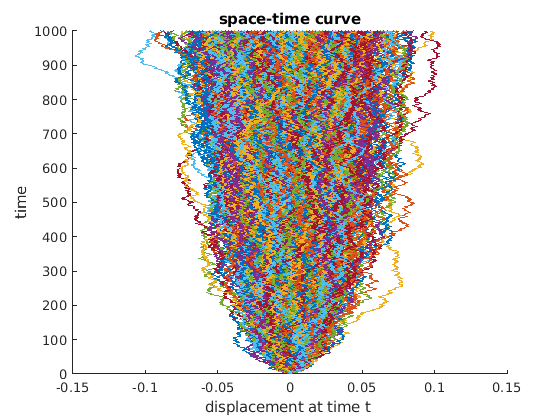

hold on;
for i=1:1:1000
    plot(q(:,i),time);
end
xlabel 'displacement at time t ';
ylabel 'time';
title 'space-time curve';
hold off;